# Getting Started with Model Debugger for SimBiology

## Description

The Model Debugger for SimBiology is a MATLAB application that lets you analyze model responses, model structure, and expressions during model simulation. 

## Getting started

To install the Model Debugger for SimBiology simply doubleclick the mltbx file. You can manage installed add-ons by clicking on the Add-Ons button in the MATLAB toolstrip.

To start the Model Debugger for SimBiology type 

startSimBiologyDebugger(model) 

where m`odel` is a SimBiology model.  

For more information type for how to apply doses and variants type 

help startSimBiologyDebugger 

in the MATLAB command line window.

## Example

% Load model
model = sbmlimport('lotka');

% Configure model for simulation
configset = getconfigset(model);
configset.SolverOptions.AbsoluteTolerance = 1e-6;
configset.SolverOptions.RelativeTolerance = 1e-6;

% Define dose
dose = sbiodose('dose for y1', 'TargetName', 'y1', 'Amount', 50);

% Start Model Debugger for SimBiology for model and dose
startSimBiologyDebugger(model, dose);

## System Requirements

- MATLAB version R2019b or later and the SimBiology ™ toolbox are required to run the Model Debugger for SimBiology.

- Unit conversion is supported in MATLAB version R2020a or later.

## Features

Use the **Breakpoints** tab to specify conditions to pause the model simulation. 

 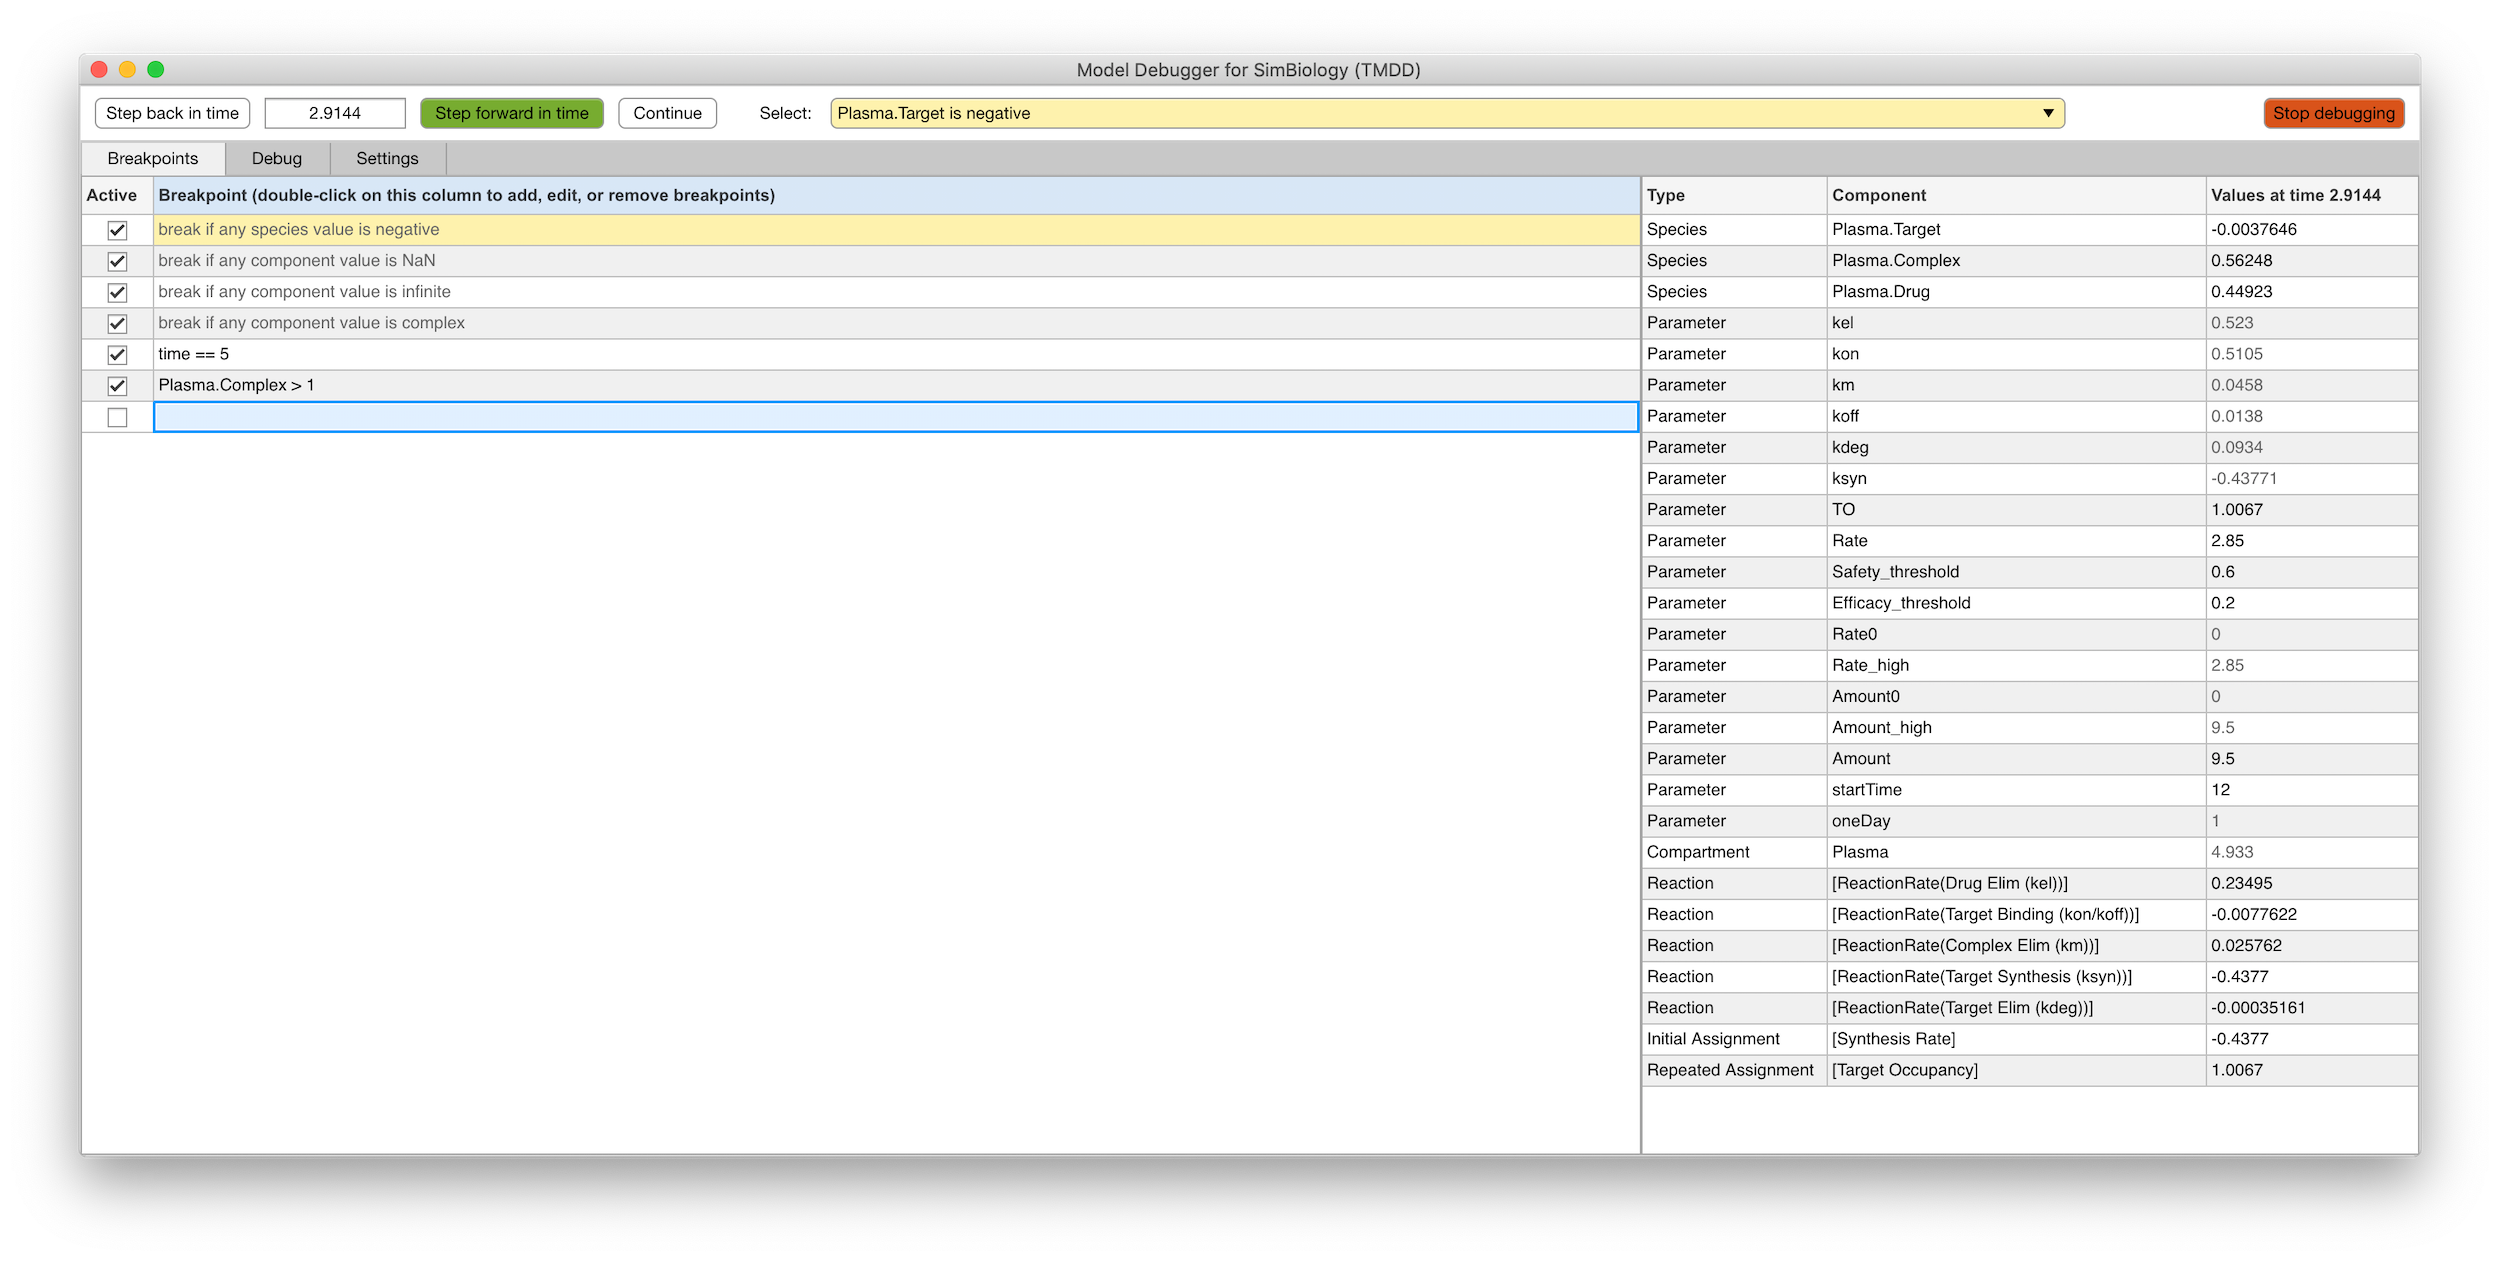

The app lets you detect if species values are negative or values of model components are NaN, Inf, or complex. Triggered breakpoints are highlighted in yellow. Select an event to investigate from the dropdown menu in the control bar located at the top of the application window. You can deactivate predefined breakpoints to continue the simulation.

Switch to the **Debug** tab to inspect model component values in the paused simulation. If you select a breakpoint from the dropdown menu in the control bar, the view automatically focuses to components involved in the breakpoint. 

 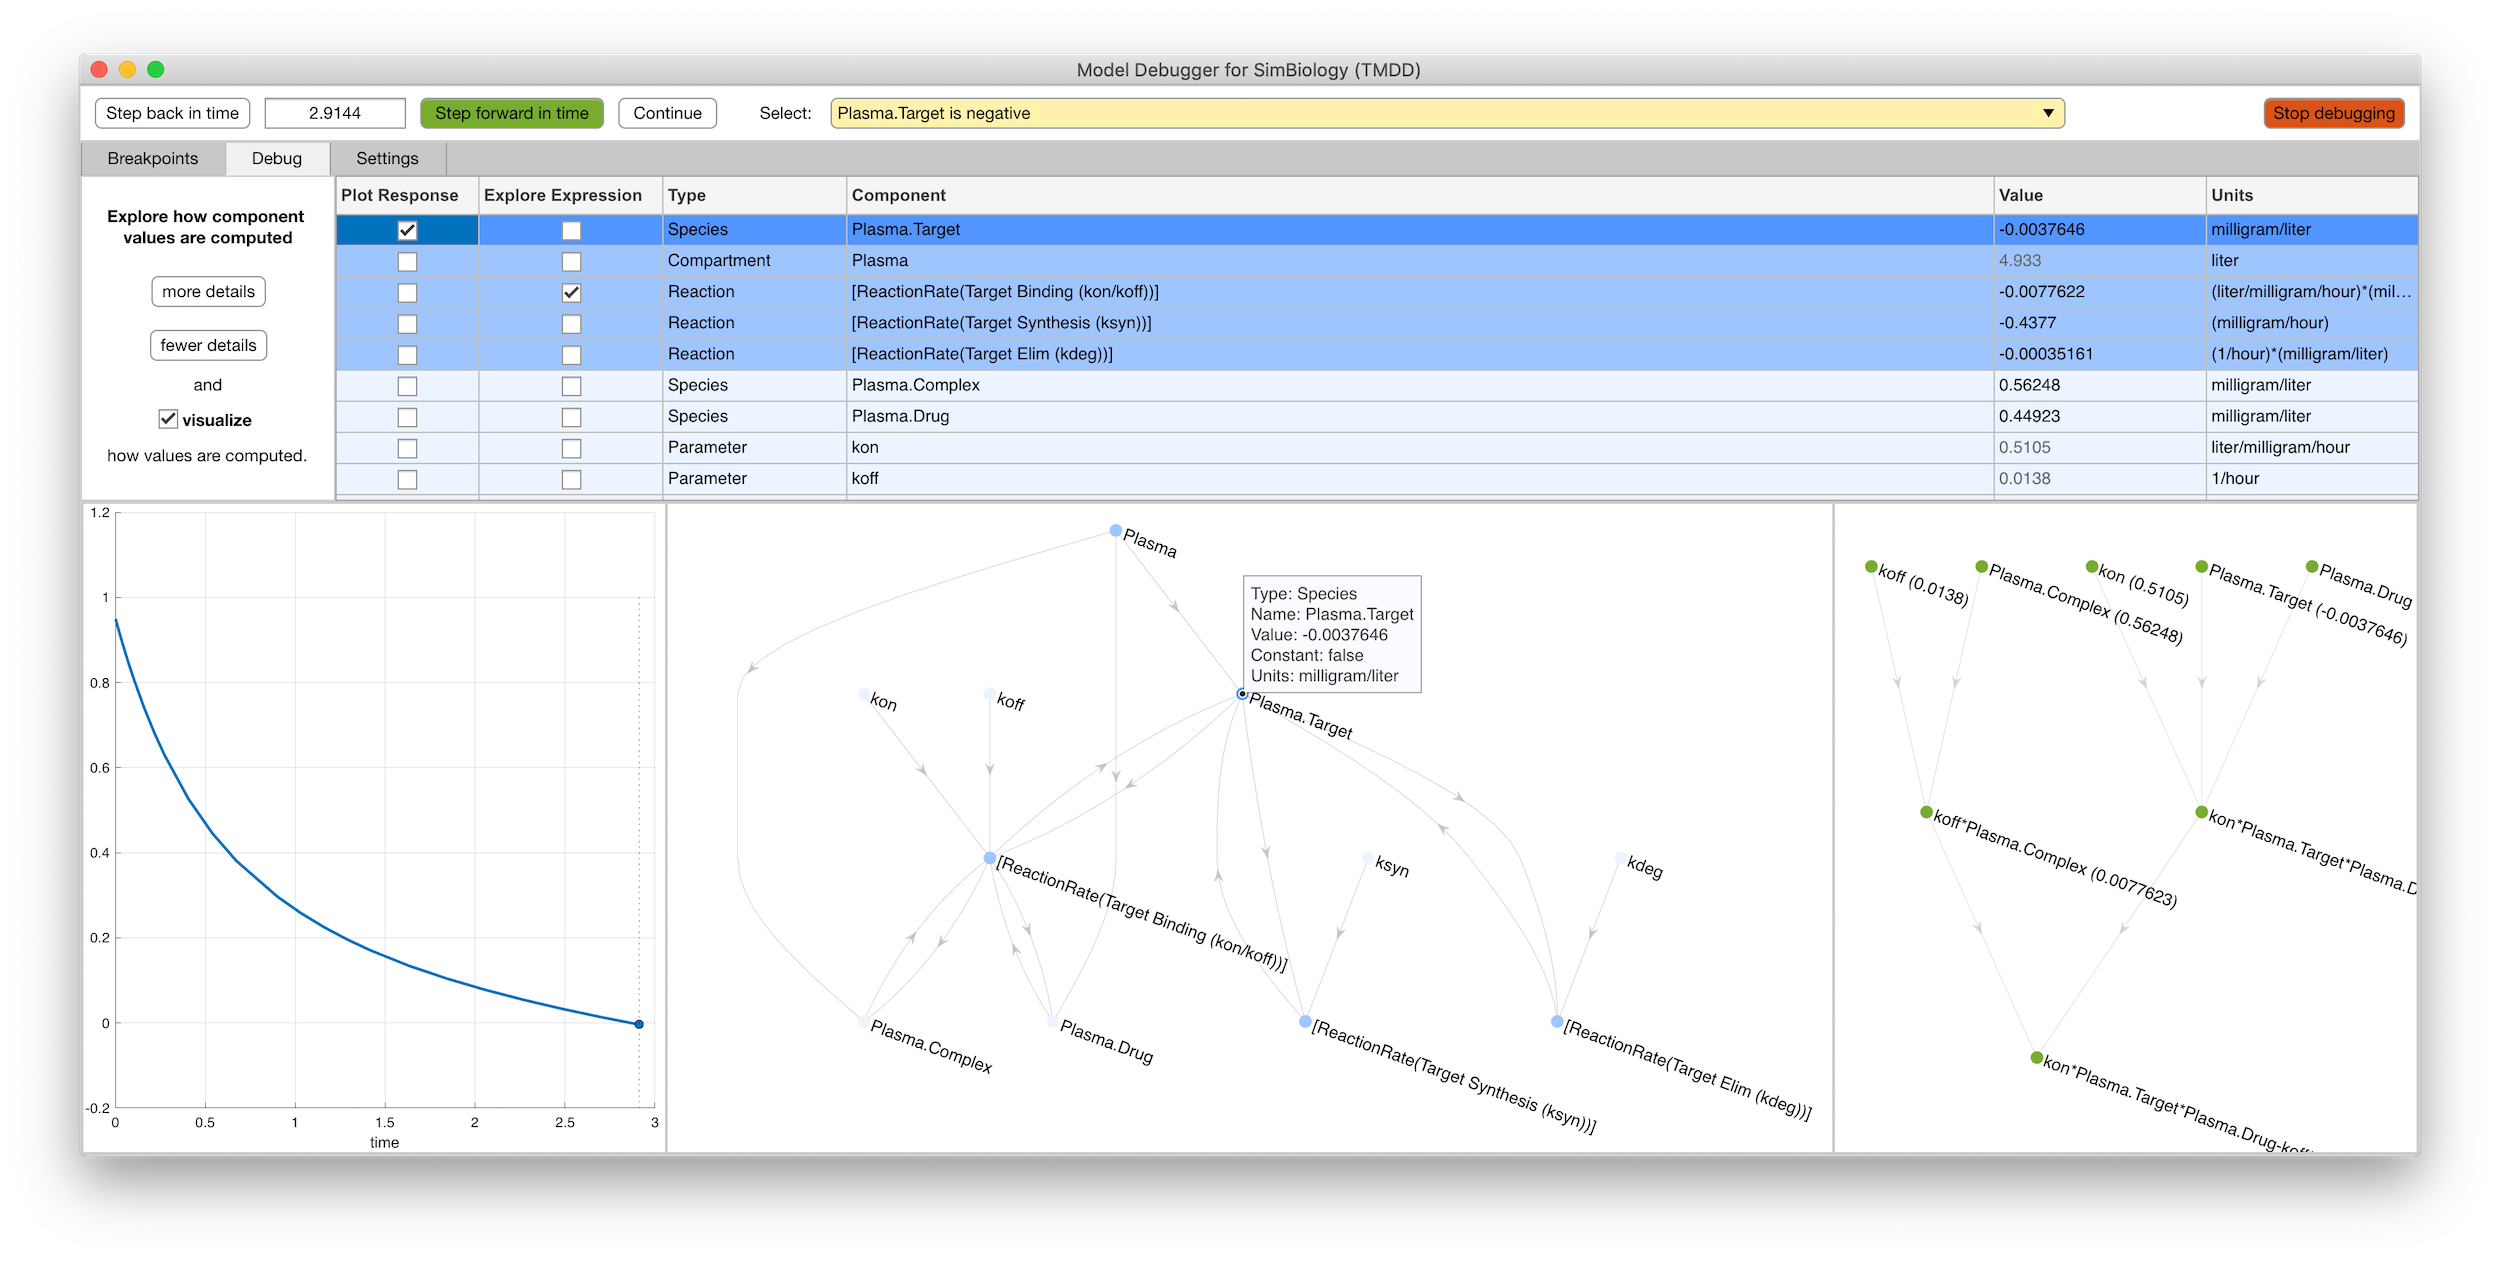

Click in the side panel to show *more details *and *visualize* the dependency graph (the middle panel) to investigate how component values are computed. Values of model components grouped by the same shade of blue are computed using values of components marked with the next lighter shade of blue. You can also plot time courses of model responses (the left panel) and explore expressions graphically (the right panel). Nodes in the expression tree represent terms that make up the expression. The color of the nodes indicates NaN (red), infinite (orange), complex (yellow), or real values (green).

Customize your preferences for model simulation and the expression view in the **Settings** panel.